# Robot-arms related tools 

Tools to model and represent and robot arms, such as the ABB irb-120 in our laboratory:

- kin_irb120

- Modelo simulink del irb120 (carpeta de archivos)

## kin_irb120

% Calculamos una determinada configuración de los 5 primeros ejes:
T=kin_irb120(5)

syms t0 t1 t2 t3 t4
conf_home = round(subs(T,{t0, t1, t2, t3, t4},...
    {0 , 0, 0, 0 , 0 }))

$$conf\_home = \left(\begin{array}{cccc} 0 & 0 & 1 & 302\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 630\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Calculamos una determinada configuración de los 6 primeros ejes:
T=kin_irb120(6)

syms t0 t1 t2 t3 t4 t5
conf_home = round(subs(T,{t0, t1, t2, t3, t4, t5},...
    {0 , 0, 0, 0 , 0 , 0}))

$$conf\_home = \left(\begin{array}{cccc} 0 & 0 & 1 & 374\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 630\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelo del robot irb120, representado en VR

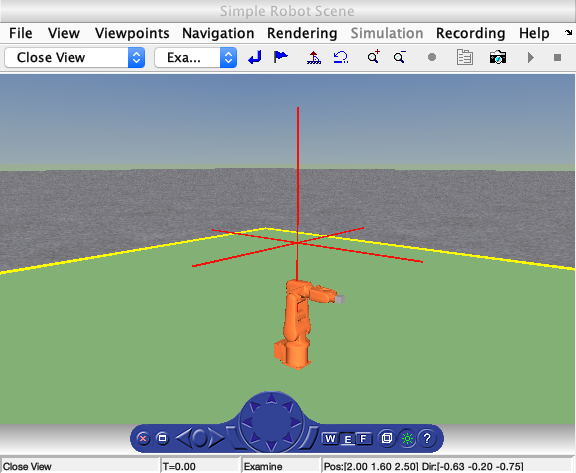

robotWorld = vrworld('robot_scene.wrl');
open(robotWorld);
rbt = importrobot('abb_irb_120d.urdf');
rbt.DataFormat = 'row';
n = vrinsertrobot(robotWorld,rbt);
vrdrawnow
view(robotWorld);

## Modelo del robot irb120, representado en Simulink

iiwaRBT = importrobot('abb_irb_120.urdf');
iiwaSM = smimport(iiwaRBT);

y ejecutar el modelo de simulink para visualizar el modelo y el robot.